## Problem Symmetrical Components Circuit 7

A balanced three-phase load is star-connected  (Y) consist of three *R**Y* = 10Ω resistors, the neutral point is not connected to ground; the supply voltage is:

*Vab* = (100∠0°) V, *V**bc* = (90∠240°) V, *V**ca*= (95.5∠125.2°) V

- Determine the sequence voltages (*V**ab1*, *V**ab2*, and *V**ab0*).                

- Determine the sequence voltages (*V**an1*, *V**an2*, and *V**an0*).               

- Considering the neutral point is not connected to ground, calculate the phase voltages (*V**an*, *V**bn* and *V**cn*).                                                  

- Considering the neutral point is not connected to ground, calculate the sequence line currents (*I**a1*, *I**a2* and *I**a0*).                                              

- Considering the neutral point is not connected to ground, calculate the phase currents (*I**a*, *I**b* and *I**c*).     

Created by: Professor Francisco Gonzalez-Longatt, May 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

Github: [https://github.com/fglongatt/Fault_Analysis](https://github.com/fglongatt/Fault_Analysis)

Reseach Gate: [https://www.researchgate.net/project/Power-System-Analysis-6](https://www.researchgate.net/project/Power-System-Analysis-6) 

clc
clear
Vab = 100   * exp(i * 0 * pi/180);
Vbc = 90.0  * exp(i * 240 * pi/180);
Vca = 95.5  * exp(i * 125.2 * pi/180);
R = 10

R = 10

Z0 = R;      % Positive sequence impedance
Z1 = R;      % Negative sequence impedance
Z2 = R;      % Zero sequence impedance

The phasor diagram results:

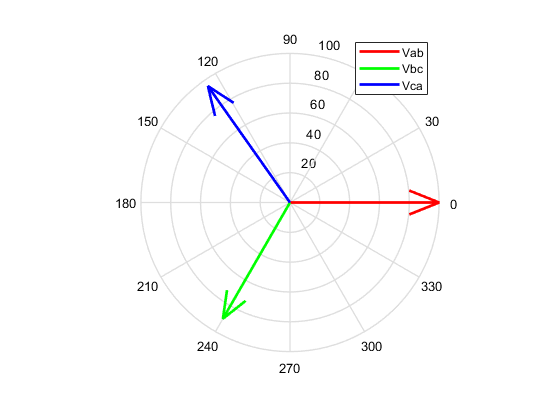

figure;
h=compass(Vab,'r'); hold on;
set(h, 'LineWidth',2);
h=compass(Vbc,'g');
set(h, 'LineWidth',2);
h=compass(Vca,'b');
set(h, 'LineWidth',2);
legend('Vab','Vbc','Vca');

Creating Vabc vector 

Vabc = [Vab; Vbc; Vca];

Defining a operator

a = 1 * exp(i*120*pi/180);

Defining A matrix

A= [1 1 1; 1 a^2 a; 1 a a^2]

A =    1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i
   1.0000 + 0.0000i  -0.5000 - 0.8660i  -0.5000 + 0.8660i
   1.0000 + 0.0000i  -0.5000 + 0.8660i  -0.5000 - 0.8660i


A1 = inv(A)

A1 =    0.3333 - 0.0000i   0.3333 + 0.0000i   0.3333 + 0.0000i
   0.3333 + 0.0000i  -0.1667 + 0.2887i  -0.1667 - 0.2887i
   0.3333 + 0.0000i  -0.1667 - 0.2887i  -0.1667 + 0.2887i


V012= A1 * Vabc ;

Separating the components

Vab0 = V012(1);
Vab1 = V012(2);
Vab2 = V012(3);

Printing results

fprintf(' Vab0 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Vab0),imag(Vab0), abs(Vab0), angle(Vab0)*180/pi)

 Vab0 = (-0.01643 + j0.03168) V = (0.03569 ∠ 117.40770°) V

fprintf(' Vab1 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Vab1),imag(Vab1), abs(Vab1), angle(Vab1)*180/pi)

 Vab1 = (95.03565 + j2.88514) V = (95.07944 ∠ 1.73888°) V

fprintf(' Vab2 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Vab2),imag(Vab2), abs(Vab2), angle(Vab2)*180/pi)

 Vab2 = (4.98078 + j-2.91682) V = (5.77200 ∠ -30.35392°) V

The phasor diagram results:

Van1 = 1/sqrt(3) * exp(i * -30 * pi/180) * Vab1;
Van2 = 1/sqrt(3) * exp(i * +30 * pi/180) * Vab2;
Van0 = Vab0;
fprintf(' Van0 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Van0),imag(Van0), abs(Van0), angle(Van0)*180/pi)

 Van0 = (-0.01643 + j0.03168) V = (0.03569 ∠ 117.40770°) V

fprintf(' Van1 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Van1),imag(Van1), abs(Van1), angle(Van1)*180/pi)

 Van1 = (48.35069 + j-25.99186) V = (54.89414 ∠ -28.26112°) V

fprintf(' Van2 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Van2),imag(Van2), abs(Van2), angle(Van2)*180/pi)

 Van2 = (3.33240 + j-0.02058) V = (3.33246 ∠ -0.35392°) V

Creating V012 vector 

V012 = [Van0; Van1; Van2];
Vabc = A * V012 ;

Separating the components

Van = Vabc(1);
Vbn = Vabc(2);
Vcn = Vabc(3);
fprintf(' Van = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Van),imag(Van), abs(Van), angle(Van)*180/pi)

 Van = (51.66667 + j-25.98076) V = (57.83117 ∠ -26.69569°) V

fprintf(' Vbn = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Vbn),imag(Vbn), abs(Vbn), angle(Vbn)*180/pi)

 Vbn = (-48.34976 + j-25.94908) V = (54.87307 ∠ -151.77776°) V

fprintf(' Vcn = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Vcn),imag(Vcn), abs(Vcn), angle(Vcn)*180/pi)

 Vcn = (-3.36619 + j52.02489) V = (52.13368 ∠ 93.70207°) V


Ia0 = Van0/Z0;
Ia1 = Van1/Z1;
Ia2 = Van2/Z2;
fprintf(' Ia0 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Ia0),imag(Ia0), abs(Ia0), angle(Ia0)*180/pi)

 Ia0 = (-0.00164 + j0.00317) V = (0.00357 ∠ 117.40770°) V

fprintf(' Ia1 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Ia1),imag(Ia1), abs(Ia1), angle(Ia1)*180/pi)

 Ia1 = (4.83507 + j-2.59919) V = (5.48941 ∠ -28.26112°) V

fprintf(' Ia2 = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Ia2),imag(Ia2), abs(Ia2), angle(Ia2)*180/pi)

 Ia2 = (0.33324 + j-0.00206) V = (0.33325 ∠ -0.35392°) V

Creating I012 vector 

I012 = [Ia0; Ia1; Ia2];
Iabc = A * I012 ;
Ia = Iabc(1);
Ib = Iabc(2);
Ic = Iabc(3);
fprintf(' Ia = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Ia),imag(Ia), abs(Ia), angle(Ia)*180/pi)

 Ia = (5.16667 + j-2.59808) V = (5.78312 ∠ -26.69569°) V

fprintf(' Ib = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Ib),imag(Ib), abs(Ib), angle(Ib)*180/pi)

 Ib = (-4.83498 + j-2.59491) V = (5.48731 ∠ -151.77776°) V

fprintf(' Ic = (%5.5f + j%5.5f) V = (%5.5f ∠ %5.5f°) V', real(Ic),imag(Ic), abs(Ic), angle(Ic)*180/pi)

 Ic = (-0.33662 + j5.20249) V = (5.21337 ∠ 93.70207°) V